# Main script

Within this file, everything you need to find and evaluate your magnetic field can be found! Make sure to modify values where it's suggested, and to only run the blocks you need!

## Determine magnetic moment of dipoles

Simulate the magnetic field which arises from a collection of ideal magnetic dipoles, and determine how their magnetization should be set to achieve a target magnetic profile.

### Set general parameters

%% Here, specify where all dipoles are located. These position must me
% explicitly specified. Each row corresponds to a dipole, and its columns
% are x, y and z positions.
dipole_positions = dipole_array(linspace(-2, 2, 3), linspace(-2, 2, 3), [-1 1]);

% Now, for each dipole, specify its magnetic moment. Every row should
% relate to the magnetic moment of the dipole of the same row in
% 'dipole_positions'. Set values to 'nan' to indicate that the values
% should be determined by a target field.
dipole_M = repmat([0, 0, nan], height(dipole_positions), 1);

% Here, specify on which domain to evaluate the B-field. Currently, only
% discs normal to the z-axis are available
target_domain = graphene([0, 0, 1], 1, pi/4);

% Finally, specify the target magnetic field profile. Any undetermined dipole
% magnetizations will be set to approximate this field, on a 2D-domain
% defined above.
target_field_elementwise = B_field_linear_x(target_domain, 1);

### Set computational parameters

These parameters only affect the computational accuracy, not the problem statement

%% Ö
collision_threshold = 0.01;

### Compute stuff

Now, let the magic happen! 

%% Check if any dipole is situated exactly in the evaluation area 
dipole_in_domain = false;
% Use line below (but fix it plz) if you're really worried about this
% any(dipole_positions(:, 3) == target_domain.Z)

threshold = collision_threshold * dipole_in_domain;

% Create function from degrees-of-freedom to magnetization:
n = sum(isnan(dipole_M), 'all');
get_M = @(x) insert_params(x, dipole_M);

% Create function handle which returns a vector-type field computator from
% params x
B_func_from_x = @(x) B_function(@(xvar, X, Y, Z) get_field(X, Y, Z, dipole_positions, get_M(xvar), threshold), x);

% Create a reference field computator handle
B_0 = B_function(@(~, X, Y, Z) cell2mat(arrayfun(@(x, y, z) reshape(target_field_elementwise(x, y, z), [1 1 3]), X, Y, Z, 'UniformOutput', false)));

% Create an inner product evaluator, with information about evaluation
% domain.
inprod = inner_product(target_domain.R, target_domain.Origin, target_domain.Phi);

% GO!!!
[x, B_best] = granny_smith(B_func_from_x, B_0, inprod, n, true);

Starting to compute inner product between 1 and 1
It took 0.085172 s
Starting to compute inner product between 2 and 1
It took 0.11923 s
Starting to compute inner product between 2 and 2
It took 0.033556 s
Starting to compute inner product between 3 and 1
It took 0.062462 s
Starting to compute inner product between 3 and 2
It took 0.055787 s
Starting to compute inner product between 3 and 3
It took 0.037068 s
Starting to compute inner product between 4 and 1
It took 0.061171 s
Starting to compute inner product between 4 and 2
It took 0.053013 s
Starting to compute inner product between 4 and 3
It took 0.11771 s
Starting to compute inner product between 4 and 4
It took 0.046095 s
Starting to compute inner product between 5 and 1
It took 0.087574 s
Starting to compute inner product between 5 and 2
It took 0.089612 s
Starting to compute inner product between 5 and 3
It took 0.067373 s
Starting to compute inner product between 5 and 4
It took 0.12695 s
Starting to compute inner product bet

### Plotting the result

%% Select the amount of discretization points
N = 10;

% Create the mesh
% Create the mesh
[X,Y,Z] = meshgrid(linspace(-target_domain.R,target_domain.R,N),...
    linspace(--target_domain.R,-target_domain.R,N),0);

i = X.^2 + Y.^2 <= 1;

[X, Y, Z] = target_domain.Transform(X, Y, Z);


% Assigns the B-field and shows the quiver plot
B = B_best(X,Y,Z);
Bx = squeeze(B(:,:,1));

Bx =     1.3643    1.3396    1.2791    1.2216    1.1872    1.1839    1.2122    1.2649    1.3221    1.3457
    0.8278    0.9351    0.9651    0.9638    0.9564    0.9536    0.9570    0.9565    0.9272    0.8235
    0.3985    0.6188    0.7142    0.7526    0.7635    0.7587    0.7446    0.7086    0.6176    0.4054
    0.1914    0.4435    0.5555    0.6108    0.6341    0.6063    0.5917    0.5499    0.4450    0.2025
    0.2771    0.4183    0.4876    0.5337    0.7924    0.2770    0.5063    0.4842    0.4193    0.2826
    0.5426    0.4892    0.4833    0.4776    0.2384    0.7539    0.5051    0.4868    0.4881    0.5368
    0.7416    0.5696    0.5104    0.4861    0.4771    0.5047    0.5048    0.5149    0.5662    0.7278
    0.7730    0.6112    0.5425    0.5136    0.5049    0.5093    0.5201    0.5448    0.6070    0.7585
    0.7242    0.6289    0.5764    0.5486    0.5374    0.5393    0.5524    0.5786    0.6265    0.7138
    0.7189    0.6723    0.6293    0.5978    0.5823    0.5843    0.6027    0.6341    0.

By = squeeze(B(:,:,2));

By =    -1.6326   -1.0604   -0.6512   -0.3536   -0.1195    0.0933    0.3245    0.6156    1.0142    1.5707
   -1.2267   -0.7890   -0.4850   -0.2660   -0.0938    0.0634    0.2348    0.4504    0.7470    1.1724
   -0.7695   -0.4822   -0.2958   -0.1660   -0.0666    0.0269    0.1321    0.2634    0.4461    0.7250
   -0.3199   -0.1894   -0.1147   -0.0706   -0.0569   -0.0250    0.0330    0.0863    0.1603    0.2865
    0.0475    0.0465    0.0350    0.0156   -0.1825   -0.2026   -0.0430   -0.0570   -0.0689   -0.0710
    0.2510    0.1987    0.1398    0.0772   -0.1611   -0.2202   -0.1006   -0.1575   -0.2163   -0.2690
    0.3118    0.2784    0.2049    0.1163    0.0080   -0.0780   -0.1414   -0.2200   -0.2928   -0.3283
    0.3449    0.3285    0.2503    0.1504    0.0431   -0.0620   -0.1629   -0.2600   -0.3392   -0.3598
    0.4314    0.3904    0.2953    0.1806    0.0603   -0.0607   -0.1812   -0.2976   -0.3962   -0.4426
    0.5968    0.4869    0.3520    0.2126    0.0747   -0.0628   -0.2033   -0.3473   -0.

Bz = squeeze(B(:,:,3));

Bz =    -0.5478   -0.4315   -0.3111   -0.1882   -0.0646    0.0590    0.1824    0.3048    0.4240    0.5385
   -0.7049   -0.5325   -0.3737   -0.2221   -0.0750    0.0707    0.2180    0.3691    0.5262    0.6956
   -0.6154   -0.4940   -0.3582   -0.2163   -0.0741    0.0699    0.2155    0.3581    0.4932    0.6139
   -0.3509   -0.3672   -0.2933   -0.1831   -0.0692    0.0579    0.1915    0.3016    0.3753    0.3630
   -0.0772   -0.2324   -0.2184   -0.1297    0.0119    0.1176    0.1750    0.2377    0.2496    0.1029
    0.0211   -0.1594   -0.1683   -0.1002    0.0229    0.1108    0.1498    0.1924    0.1819    0.0107
   -0.0704   -0.1594   -0.1515   -0.0996   -0.0381    0.0388    0.1203    0.1732    0.1825    0.0999
   -0.2005   -0.1882   -0.1507   -0.0947   -0.0289    0.0423    0.1121    0.1703    0.2093    0.2240
   -0.2462   -0.1965   -0.1477   -0.0906   -0.0262    0.0414    0.1068    0.1647    0.2139    0.2634
   -0.1820   -0.1661   -0.1359   -0.0881   -0.0277    0.0377    0.0989    0.1474    0.

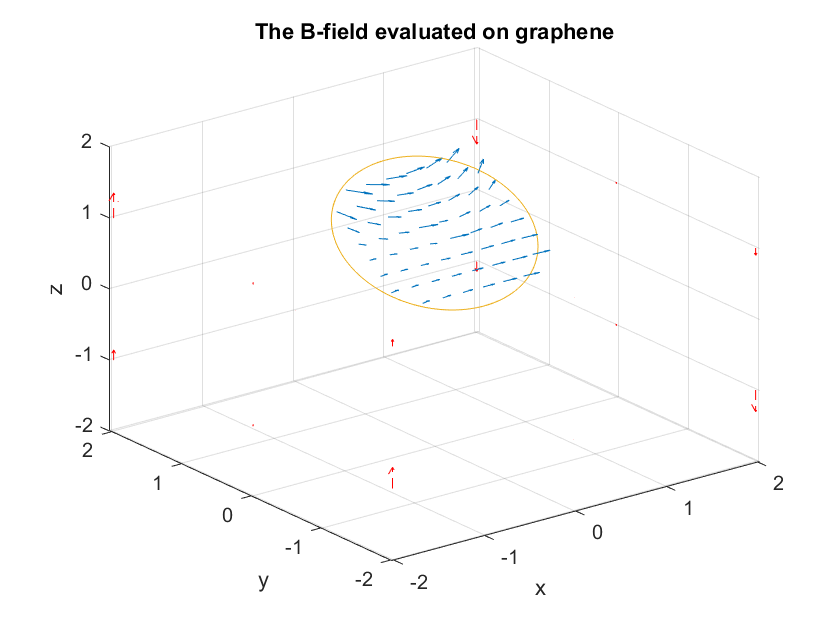


m = get_M(x);

b_plot(X(i),Y(i),Z(i),Bx(i), By(i), Bz(i) ,dipole_positions,m,target_domain)